# **Rotational Workspace for Cable-Driven Haptic Device (CDHD) in IMT. **

**Autor: Ing Tien Khaw**

## **Introduction**

This is a Matlab Live Script programme use to simulate the workspace by defining the parameter such as the:

- length 

- width

- height

- rod length

- wrench

- stepsize

- rotation angles  

By changing the parameter, the workspace of the CDHD will be influenced. This programme should be able to deliver 3D figures which allow the viewer to have a better understanding about the influence of each parameter on the workspace of the CDHD. 

clear
clc
% close all
evaluation_timer=tic;

%%Define Parameter here 
noC = 8;

## Design of HDHD

After considering different types of possible configurations with Falcon design, which is first inspired by researcher [Kawamura](http://rraj.rsj-web.org/en_atcl/1366), we have come to a final decision due to its light weight, and simple design. The final design of CDHD has been showed in the following figure. The Falcon design consists of a base frame, an endeffector and 8 cables and winches. From the tip of the endeffector to the corner of the frame, a total of 8 cables would be linked. The top of the frame has 4 winches (w1, w2, w3, and w4) at each corner and 4 cables. The lower side of the frame has 4 winches (w5, w6, w7, and w8) at each corner and 4 cables link to the bottom of the rod. 

The region of interest (ROI): ROI has been defined as a cylinder with the diameter of 300 mm and height of 200 mm, which can be seen as the purple object in the figure. For the best configuration, the workspace from the haptice device should be able to cover the whole cylinder. 

Geometry of frame: The frame (red object in the figure) has been constructed in a square form, so that it could provide a symmetry workspace both in x- and y-direction. Therefore, ax and ay length would always be the same.

[Endeffector](https://en.wikipedia.org/wiki/Robot_end_effector), also known as mobile platform or manipulator: In this work, the mobile platform is a rigid rod made from carbon which has a maximum defined length of 600 mm and diameter of 10 mm. At the bottom of the mobile platform, there will be a user interface gripper be integrated. The user will control the gripper to move the CDHD within the reachable workspace. 

Degree of Freedom (DoF): The Falcon design with point shaped endeffector allowed a movement of 2R3T, resulted in 5 DoF. (TODO:Figure)

Trocar point: For the usage of haptic device in robot assisted surgery, the mobility of the Instrument would be limited to just 3 DoF, which can be seen in the following figure (TODO). Therefore, a virtual trocar point would be introduced to the CDHD. The trocar point would be exactly in the middle of the frame. 

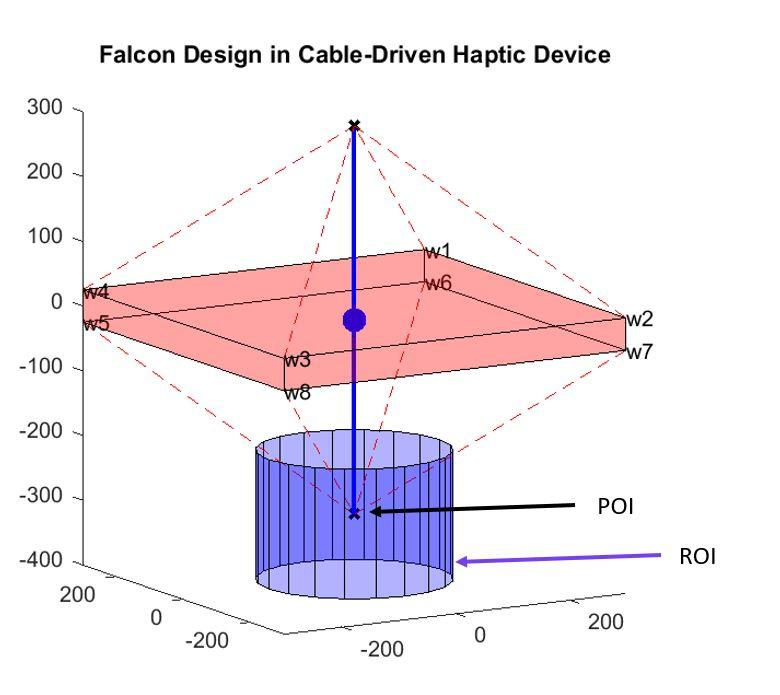

## Define iteration for z-axis (Translation in z-direction)

The z-translation of the rod would be done in an iterative way. In each loop, there will be total of ***grid_n*** points being checked, with a stepsize of ***grid_delta*** between the ***grid.z_min*** and ***grid.z_max***.

%Define max and min of grid in z-direction
grid.z_max = 50;
grid.z_min = -600;

%Define grid_n   
grid_n = 50;  %stepsize in x- and y-direction 
grid_delta = (grid.z_max - grid.z_min) / grid_n;  %discretization steps in x-direction in mm %Gitterabstand von X-Richtung (Y- & Z-Richtung auch in diesem Abstand)

coordinate.x = 0; %step size in x-direction
coordinate.y = 0; %step size in y-direction
coordinate.z = (grid.z_min : grid_delta: grid.z_max)'; %step size in z-direction

disp(['There will be a total of ' num2str(length(coordinate.z)) ' points beeing checked in z-translation with a stepsize of ' num2str(grid_delta) 'mm between ' num2str(grid.z_min) 'mm and ' num2str(grid.z_max) 'mm'])

There will be a total of 51 points beeing checked in z-translation with a stepsize of 13mm between -600mm and 50mm


## Define wrench (either 5N or 0N = no wrench)

If wrench is activated, then the workspace would be smaller. 

wrench = "Yes";
switch wrench
    case "Yes"
    w_p = 5; %N wrench in x-y-z direction 
    w_p_t = 5; %N wrench in Torque in x-y direction (Feedback Kraft in Rotation)
    case "No"
    w_p = 0; 
    w_p_t =0;
end

## Parameter for workspace calculation

## Definition of cable force limit from motor 

The rated torque (Ger: Nenndrehmoment) is therefore the maximum permissible continuous torque that may act on the output shaft of the drive. The rated torque is determined by the continuous power of the electric motor or by the continuous load of the mounted gear unit. 

The minimum cable force needed is defined as 5N based on the experience. The minimum force is needed to prevent the cable from entering a sagging position, which could lead to the false calculations. For the maximum cable force, ones can calculate from the maximum rated torque from the motor. 


$$\tau =F_{\max } \cdot l\;\;\;\;$$


Mn = 183; %rated torque in unit mNm for Motor 
L_winde = 4.5; %mm %Stand:21.09.2022
f_min = 5; %Newton to prevent the cable from sagging  
f_max = Mn/L_winde; 

## Definition of cable force limit for algorithm

For the Improved closed-form solution methode, the $\parallel f_{V\;} \parallel_2$ need to fulfil this conditions. 

If $\parallel f_{V\;} \parallel_2$ violates the upper limit, no solution exists and if it is below the lower limit, the distribution is feasible.

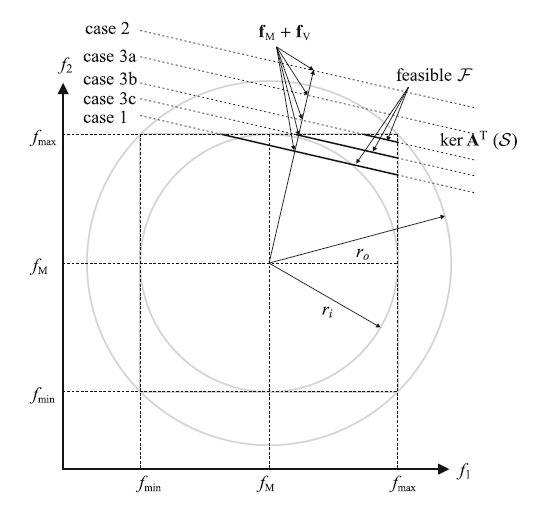

case 1. If $\parallel f_{V\;} \parallel_2 \;<r_{i\;} =\frac{1}{2}\;\left(f_{\max } -f_{\min } \right)$  then a feasible distribution exists and is bounded by theminimum and maximum forces in each cable. Furthermore, under this condition, the force distribution is additionally differentiable along a differentiable trajectory and applied wrench w_p.

case 2. If $\parallel f_{V\;} \parallel_2 \;>r_{o\;} =\frac{1}{2}\;\sqrt{m}\;\left(f_{\max } -f_{\min } \right)$, then no feasible force distribution exists and the pose does not belong to the wrench-feasible workspace for the given applied wrench w_p.

 $\frac{1}{2}\;\left(f_{\max } -f_{\min } \right)\le \;\parallel f_{V\;} \parallel_2 \;\le \;\frac{1}{2}\sqrt{m}\;\left(f_{\max } -f_{\min } \right)$  --- **(3.60) Pott's book**

with lower limit = $\frac{1}{2}\;\left(f_{\max } -f_{\min } \right)$

with upper limit = $\frac{1}{2}\sqrt{m}\;\left(f_{\max } -f_{\min } \right)$

The average feasible force of vector $f_{M\;}$ reads 

$f_{M\;} =\;\frac{\left(f_{\min \;} +f_{\max \;} \right)\;}{2}$ --** (3.53) Pott's book **

limit.lower = (1/2 * (f_max - f_min)) ; %upper limit for improve closed-form solution (eq. 3.6 Pott book)
limit.upper = (1/2 * sqrt(noC) * (f_max - f_min)); %lower limit for improved closed form (eq. 3.6 Pott book)
f_M = ones(noC,1); %preallocating for speed
f_M = f_M .* ((f_min + f_max) / 2); % f_M = average feasible force (below Eq 3.53 Pott Book)

## Definition of rotation axis

Define rotation value around the sphere. 

rotation_angles_z =  0:10:355;%rotation around z-axis 
rotation_angles_3Daxis =   0:5:80;%positive %C-bogen 

rot_axis = zeros(length(rotation_angles_z),3); %Preallocationg for speed 

%Define rotation axis matrix 
for z = 1 : length(rotation_angles_z)
    rotation_array_z = [0 0 1 deg2rad(rotation_angles_z(z))]; %rotation only at z-axis 
    rot_mat_z = axang2rotm(rotation_array_z); %create 3x3 rotation matrix at z_axis 
    rot_axis (z,:) = [1 0 0] * rot_mat_z; %rotation axis between x-axis and y-axis (start from coordinate 1 0 0)
end


## Plot rotation axis vector (1R) Example only

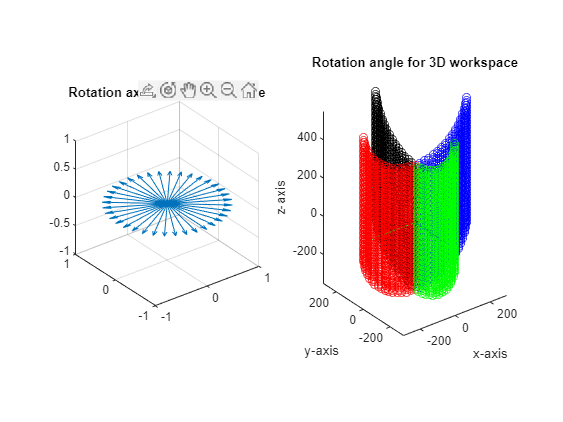

figure
subplot(1,2,1)

X = zeros(length(rotation_angles_z),1);
Y = zeros(length(rotation_angles_z),1);
Z = zeros(length(rotation_angles_z),1);
U = rot_axis(:,1);
V = rot_axis(:,2);
W = rot_axis(:,3);

hq = quiver3(X,Y,Z,U,V,W,0);
title ("Rotation axis for 3D workspace")
xlabel ('x-axis')
ylabel ('y-axis')
zlabel ('z-axis')
axis equal

%% Plot Rotation (0:30°) around rotation axis. (1R + 1R)
subplot(1,2,2)
colorstring = 'kbgr'; %define manually the colour sequence
rotation_z_angle = [1 10 19 28]; %seletion of rotation angles around z-axis

%plot Rod 
Rod_top = [0 0 300];
Rod_bottom = [0 0 -300];
Rod = [Rod_top; Rod_bottom]';
plot3(Rod(1,:), Rod(2,:), Rod(3,:),'LineWidth',2,'Color','k')
hold on 

for ix = 1:length(rotation_z_angle)
rotation_angles = rotation_z_angle(ix);
X = zeros(1,1);
Y = zeros(1,1);
Z = zeros(1,1);
U = rot_axis(rotation_angles,1)*300;
V = rot_axis(rotation_angles,2)*300;
W = rot_axis(rotation_angles,3)*300;
quiver3(X,Y,Z,U,V,W,'Color', colorstring(ix));
hold on 

    for i = 1:length(rotation_angles_3Daxis)
        rot_angle = rotation_angles_3Daxis(i);
        R = axang2rotm([rot_axis(rotation_angles,:), deg2rad(rot_angle)]);
        POI_vector = R *Rod_bottom';
        plot3(POI_vector(1,:),POI_vector(2,:),POI_vector(3,:),'o','Color', colorstring(ix))
        hold on    

%                 for k = 1:length(coordinate.z)
%                    workspace_position = [coordinate.x coordinate.y coordinate.z(k)]';
%                    POI_vector_translation = POI_vector - workspace_position;
%                    plot3(POI_vector_translation(1,:),POI_vector_translation(2,:),POI_vector_translation(3,:),'o','Color', colorstring(ix))
%                    hold on 
%                end
          
    end
end

xlabel ('x-axis')
ylabel ('y-axis')
zlabel ('z-axis')
title ("Rotation angle for 3D workspace")
axis equal

As can be seen in the above figure, the steps for for rotation around x-axis and y-axis has been showed. The first figure showed that the rotation angles from 0° to 360°, which will be used to define the rotation axis. Then the endeffector will rotate around the rotation axis, for an angles between 0° and 30° (see variable rotation_angles_3Daxis). If the second figure been viewed from above, ones can see that the rotation axis vector (arrow form) its always perpendicular to the rotation points. They have been given the same colour for better visualisation. So far 2R has been done. 

For the 1T (translation in z-axis). It would be implemented by iteratively moving the endeffector in a stepsize of 13mm (see variable grid_delta).

## Definition for frame & rod length

In this evaluation programm, there will be four cases to be choose.

- **standard**: Only a single configuration will be simulated. 4 Input variable must be given: ax_standard, ay_standard, az_standard and b_standard.  

- **ax**: For ax case, only the ax variable will be varied, based on the given ax_range. Therefore, az_standard and b_standard should have a fix values. 

- **az**: For az case, only the az variable will be varied, based on the given az_range. Therefore, ax_standard and b_standard should have a fix values.

- **b**: For b case, only the b variable will be varied, based on the given b_range. Therefore, ax_standard and az_standard should have a fix values.  

%choose one to set a changing variable
ax_range =  300:50:600; % in mm 
az_range =   0:50:300; % in mm 
b_range =  300:50:600; % in mm 

%the rest of the parameter will be fixed 
ax_standard = 510; %in mm (INPUT: total of ax) (predefined: always ax = ay) 
ay_standard = ax_standard; %in mm (INPUT: total of ay) 
az_standard = 50; %in mm (INPUT: total of az)
 b_standard =600; %in mm (INPUT: total rod lenght)


Parameter = "standard"; %Define changing parameter here 

switch Parameter
   case "standard"
        group = 0;
        [a_cell] = SetupParameter(ax_standard,ay_standard,az_standard);
        b_cell =  endeffector_parameter(b_standard);
        x_label = sprintf("standard [mm]");
        loop_length = length(b_cell);
        zeros(length(b_cell),1);

    case "ax"
        group = 1;
        [a_cell] = SetupParameter(ax_range,ay_standard,az_standard);%variety
        b_cell =  endeffector_parameter(b_standard);
        x_label = sprintf("ax length [mm]");
        loop_length = length(a_cell);

    case "az" 
        group = 2;
        [a_cell] = SetupParameter(ax_standard,ay_standard,az_range);%variety
        b_cell =  endeffector_parameter(b_standard);
        x_label = sprintf("az length [mm]");
        loop_length = length(a_cell);
        
    case "b"
        group = 3;
        [a_cell] = SetupParameter(ax_standard,ay_standard,az_standard);
        b_cell =  endeffector_parameter(b_range); %variety
        x_label = sprintf("rod length [mm]");
        loop_length = length(b_cell);

end

b = cell2mat(b_cell(1,1)); %standard parameter (it would be overwriten if its not standard)
a = cell2mat(a_cell(1,1)); %standard parameter (it would be overwriten if its not standard)

I_vv_cell = cell(max(length(a_cell), length(b_cell)),1); %predefine for speed 
Volume_ws_cell = cell(max(length(a_cell), length(b_cell)),1); %predefine for speed 
Volume_frame_cell = cell(max(length(a_cell), length(b_cell)),1); %predefine for speed 
Percentage_cell = cell(max(length(a_cell), length(b_cell)),1); %predefine for speed 
plot_x_axis = zeros(max(length(a_cell), length(b_cell)), 1); %predefine for speed

## Define Point of Interest (POI)

POI_offset = [0 0 b(3,5)]'; %first value of endeffector in z-axis (offset to half the rod length)
lever_arm = POI_offset(3); %only half of rod length

## Define the points to test for wrench

A pose **(r, R) **of a cable robot is called wrench-feasible or acceptable for a given wrench ${\mathit{\mathbf{w}}}_{\mathit{\mathbf{p}}\;}$if 

$A^{T\;} \left(r,R\right)\;f+w_{p\;} =0$  for $0<f_{\min \;} \le f_i \le f_{\max } \;$  with $i=1,\ldotp \ldotp \ldotp ,m\;$   --- **(3.15) Pott's book**

Therefore, it is necessary to define the "examination points" in all direction that need to be checked for each potential point for workspace. If the point can't have a static equilibrium when the wrench is introduced, then the point would not be considered into the workspace.  

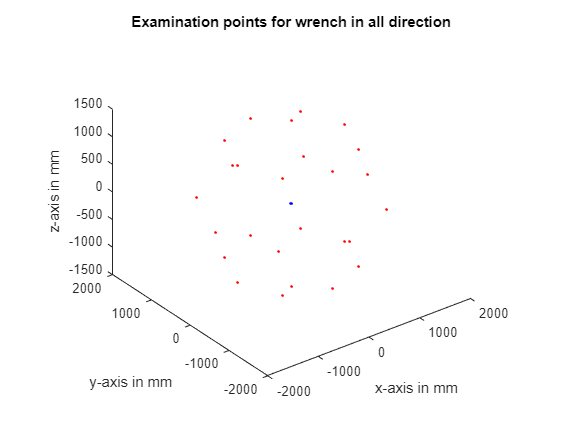

wrench_mat = wrench_multiplication_khaw (w_p, w_p_t, lever_arm);
title ('Examination points for wrench in all direction')
xlabel('x-axis in mm')
ylabel('y-axis in mm')
zlabel('z-axis in mm')

Ones can zoom into the "blue point", where the examination points for force has been plotted. As the examination points for torque is M = F*L , so the values would be relatively large. For L = 300mm, the M = 1500Nmm. 

## Start the main loop code

Elapsed time is 24.065559 seconds.


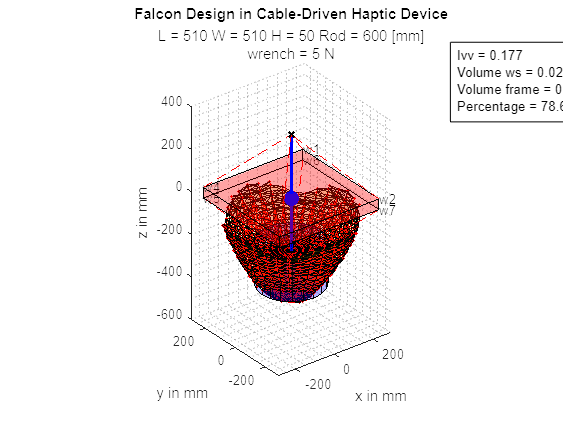

for counter = 1 : loop_length
    switch Parameter     
        case "standard"
            a = cell2mat(a_cell(1,1));
            ax_value = a(1,1)*2;
            ay_value = a(1,1)*2;
            az_value = a(3,1)*2;
            b_value = b_cell{1,1}(3)*2;
            plot_x_axis(1,1) = a(1,1)*2; %times two bcz only half of the length
            txt = ['ax = ' int2str(ax_value) ' ay = ' int2str(ay_value) ' az = ' int2str(az_value)  ' rod length = ' int2str(b_value) ' [mm]'];

        case "ax"
            a = cell2mat(a_cell(counter,1)); %variety of parameter
            ax_value = a(1,1)*2;
            ay_value = a(2,1)*2;
            az_value = a(3,1)*2;
            b_value = b_cell{1,1}(3)*2;
            plot_x_axis(counter,1) = a(1,1)*2; %times two bcz only half of the length
            txt = ['ay = ' int2str(ay_value) ' az = ' int2str(az_value)  ' rod length = ' int2str(b_value) ' [mm]']; 

        case "az"
            a = cell2mat(a_cell(counter,1)); %variety of parameter
            ax_value = a(1,1)*2; 
            ay_value = a(2,1)*2; 
            az_value = a(3,1)*2; 
            b_value = b_cell{1,1}(3)*2;
            plot_x_axis(counter,1) = a(3,1)*2;  %times two bcz only half of the length
            txt = ['ax = ' int2str(ax_value) ' ay = ' int2str(ay_value), ' rod length = ' int2str(b_value) ' [mm]']; 

        case "b"
            a = cell2mat(a_cell);
            ax_value = a(1,1)*2; %same as ax_standard
            ay_value = a(2,1)*2; %same as ax_standard
            az_value = a(3,1)*2; %same as ax_standard
            b = cell2mat(b_cell(counter,1)); %variety of parameter
            b_value = b(3,1)*2; %times two bcz only half of the length
            plot_x_axis(counter,1) = b_value; 
            txt = ['ax = ' int2str(ax_value) ' ay = ' int2str(ay_value), ' az = ' int2str(az_value) ' [mm]']; 

    end

        total_counter = 0; %reset counter  
        [workspace_trans_remove_OutL,vol_results_remove_OutL,cable_length_mat_cell_mat] = maincode_khaw_live2(a,b,noC,coordinate,w_p,w_p_t,rotation_angles_z,rotation_angles_3Daxis,rot_axis,f_min,f_max,limit,f_M,POI_offset,wrench_mat);
        
        % 4 specs analysis
        [I_vv,Volume_ws,Volume_frame] = evaluation_volume(vol_results_remove_OutL,ax_value,ay_value,b_value);
        [Percentage,Vol_point_in_ROI]  = Percentage_within_ROI(workspace_trans_remove_OutL,b_value);

        I_vv_cell{counter} = I_vv; 
        Volume_ws_cell{counter} = Volume_ws;
        Volume_frame_cell{counter} = Volume_frame;
        Percentage_cell{counter} = Percentage;  


[vol_results] = ws_plot_winner_khaw(workspace_trans_remove_OutL,a,b,noC,I_vv,Volume_ws*1e-9,Volume_frame*1e-9,Percentage,w_p);


% %save figure automatically
% path = 'D:\Masterarbeit\11_MATLAB_GIT\6. rotational workspace_khaw_Evaluation\figure\20220912';
% filename = "rotational_workspace_%d_%d_%d_%d_%d";
% filename_total = sprintf(filename,group, round(ax_value,0) ,round(ay_value,0), round(az_value,0), round(b_value,0));
% saveas(gcf,fullfile(path,filename_total),'fig');
% close(gcf)

end


I_vv_mat = cat(1,I_vv_cell{:});
Volume_ws_mat = cat(1,Volume_ws_cell{:});
Volume_frame_mat = cat(1,Volume_frame_cell{:});
Percentage_mat = cat(1, Percentage_cell{:});


% evaluation_plot(plot_x_axis,I_vv_mat,Volume_ws_mat,Volume_frame_mat,Percentage_mat,x_label,txt);

%save figure automatically
% path = 'D:\Masterarbeit\11_MATLAB_GIT\6. rotational workspace_khaw_Evaluation\figure\20220912';
% filename = "rotational_workspace_%d_%s";
% filename_total = sprintf(filename,group,x_label);
% saveas(gcf,fullfile(path,filename_total),'fig');
% close(gcf)


disp(strcat("Total execution time: ", num2str(toc(evaluation_timer)), "s"))

Total execution time: 76.4375s
